This script analyzes the correlation between the timecourses of independent components from a resting-state dataset and whisker motion.

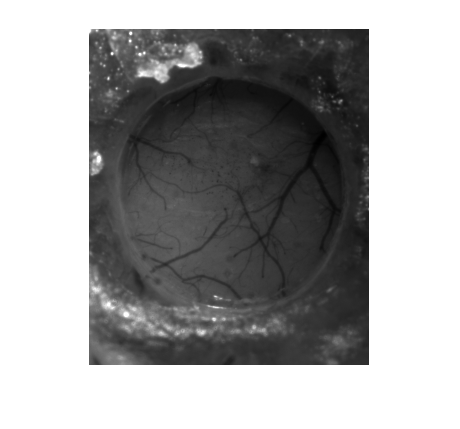

%Extract and pre-process brain imaging data
dataFolderPath = 'E:\Data Jeremie\Bilateral Stim and Resting State dataset\M4\M4_rs_10min';
greenMovie = ImagingMovie(dataFolderPath,'green');
greenMovie.correctMotion;

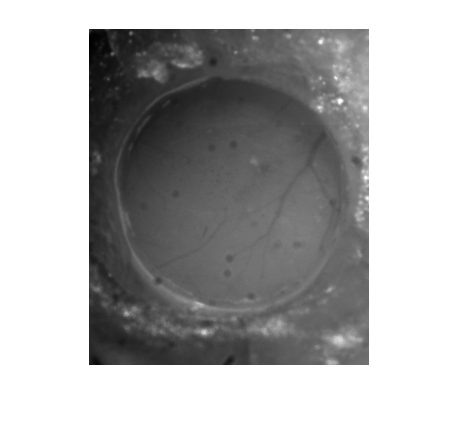

redMovie = ImagingMovie(dataFolderPath,'red');
redMovie.correctMotion;

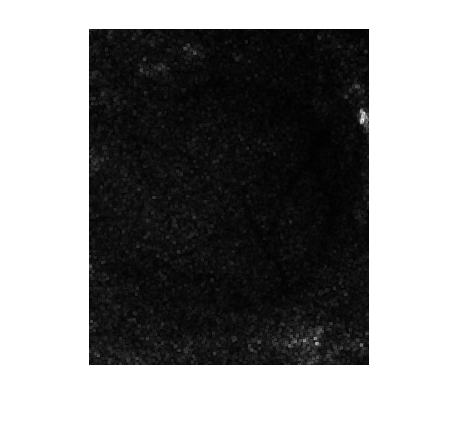

speckleContrastMovie = ImagingMovie(dataFolderPath,'speckle');
speckleContrastMovie.correctMotion;

greenMovie.normalizeByMean;
redMovie.normalizeByMean;
[HbOMovie, HbRMovie] = convertToHb(greenMovie.data,redMovie.data);
speckleContrastMovie.convertToSpeckleContrast(5);
HbOMovie = ImagingMovie(dataFolderPath,'HbO',HbOMovie);
HbRMovie = ImagingMovie(dataFolderPath,'HbR',HbRMovie);
clear greenMovie redMovie
HbOMovie.gaussianFilter(1);
HbRMovie.gaussianFilter(1);
speckleContrastMovie.gaussianFilter(1);
HbOMovie.zscore;
HbRMovie.zscore;
speckleContrastMovie.zscore;
mask = HbOMovie.createMask;
HbOMovie.applyMask(mask);
HbRMovie.applyMask(mask);
speckleContrastMovie.applyMask(mask);

%Extract independent components and their timecourses
HbOMatrix = HbOMovie.convertTo2DMatrix(mask);
HbRMatrix = HbRMovie.convertTo2DMatrix(mask);
SCMatrix = speckleContrastMovie.convertTo2DMatrix(mask);
n = 10;
[componentsHbO, wHbO, tHbO] = fastICA(HbOMatrix,n,'negentropy');
[componentsHbR, wHbR, tHbR] = fastICA(HbRMatrix,n,'negentropy');
[componentsSC, wSC, tSC] = fastICA(SCMatrix,n,'negentropy');
A_HbO = tHbO\wHbO'; %A is the matrix that holds the mixing weights
A_HbR = tHbO\wHbR';
A_SC = tSC\wSC';

%Extract whisker motion signal
videoPath = 'E:\Data Jeremie\Bilateral Stim and Resting State dataset\M4\M4_rs_10min\M4_rs_monitoring.avi';
syncFilePath = 'E:\Data Jeremie\Bilateral Stim and Resting State dataset\M4\M4_rs_10min\M4_rs_monitoring.mat';
monitoringVideo = webcamMovie(videoPath,syncFilePath);
whiskerMask = monitoringVideo.createMask;
rawWhiskerSignal = monitoringVideo.extractROIsignal(whiskerMask);

whiskerSignal = monitoringVideo.synchronizeSignal(rawWhiskerSignal);

Error using webcamMovie/synchronizeSignal
Method 'synchronizeSignal' is not defined for class 'webcamMovie' or is removed from MATLAB's search path.

whiskerSignal = (whiskerSignal-mean(whiskerSignal))/std(whiskerSignal);
whiskerME = [0 ;abs(diff(whiskerSignal))]; %add initial zero to make vectors same size
whiskerME = (whiskerME-mean(whiskerME))/std(whiskerME);

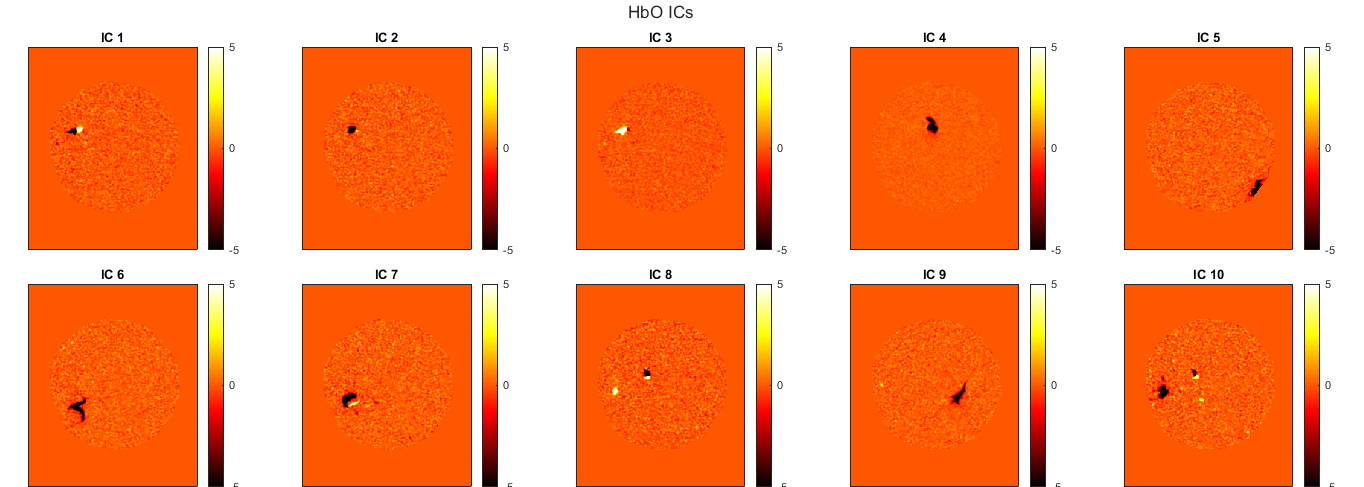

%Display independent components
figure('Color',[1 1 1],'Position',[1531,69,1446,516]);
map = zeros(size(mask));
t = tiledlayout(ceil(n/5),5);
t.TileSpacing = 'compact';
t.Padding = 'none';
t.Title.String = 'HbO ICs';
for i = 1:n
    nexttile;
    map(find(mask))=componentsHbO(i,:);
    imagesc(map,[-5 5]);
    title(['IC ' num2str(i)]);
    colorbar;
    colormap hot;
    axis image;
    xticks([]);
    yticks([]);
end

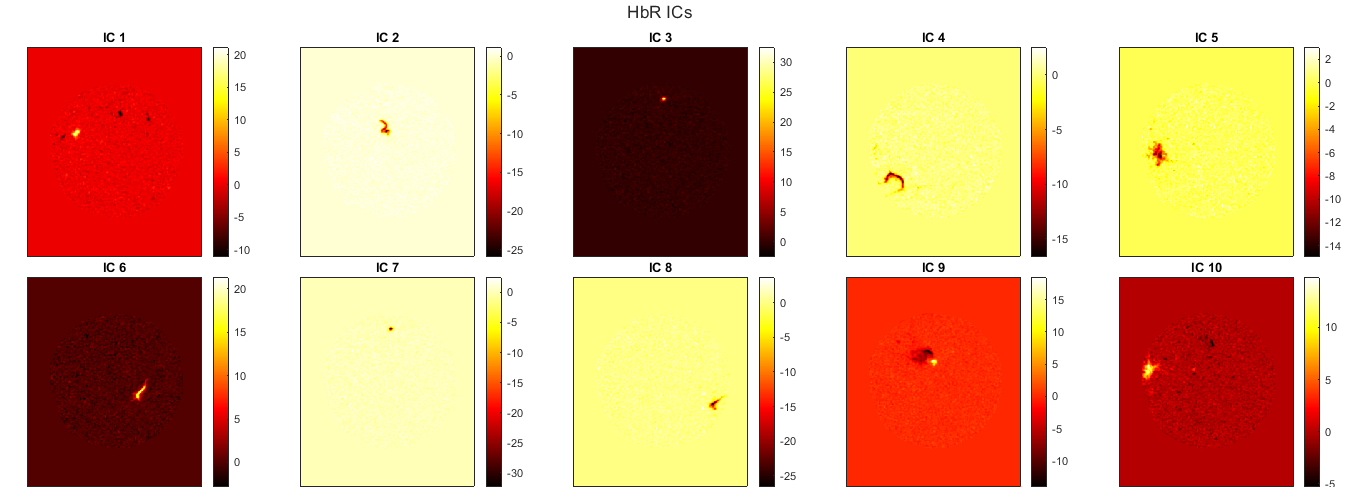


figure('Color',[1 1 1],'Position',[1531,69,1446,516]);
map = zeros(size(mask));
t = tiledlayout(ceil(n/5),5);
t.TileSpacing = 'none';
t.Padding = 'none';
t.Title.String = 'HbR ICs';
for i = 1:n
    nexttile;    
    map(find(mask))=componentsHbR(i,:);
    imagesc(map);
    title(['IC ' num2str(i)]);
    colorbar;
    colormap hot;
    axis image;
    xticks([]);
    yticks([]);
end

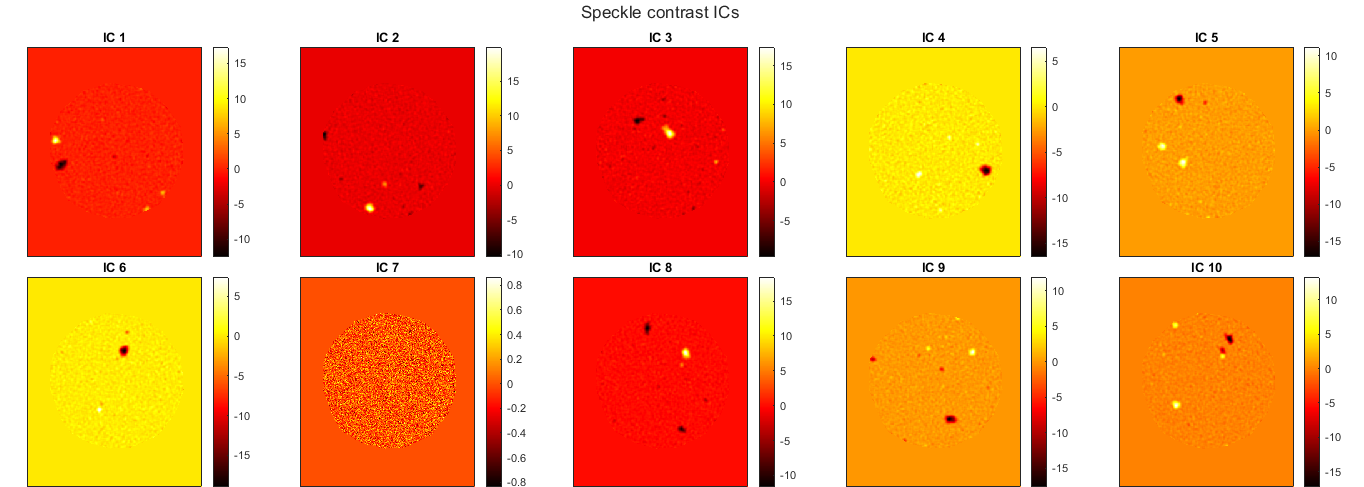


figure('Color',[1 1 1],'Position',[1531,69,1446,516]);
map = zeros(size(mask));
t = tiledlayout(ceil(n/5),5);
t.TileSpacing = 'none';
t.Padding = 'none';
t.Title.String = 'Speckle contrast ICs';
for i = 1:n
    nexttile;    
    map(find(mask))=componentsSC(i,:);
    imagesc(map);
    title(['IC ' num2str(i)]);
    colorbar;
    colormap hot;
    axis image;
    xticks([]);
    yticks([]);
end